# System identification Test Signals Generation

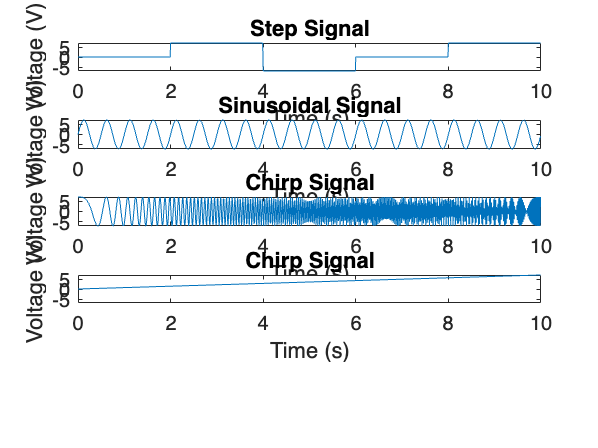


clear
% Parameters
voltage_limit = 7;        % Voltage limit (+-7V)
update_rate = 100;        % Update rate in Hz
Ts = 1 / update_rate;     % Sampling time
duration = 10;            % Signal duration in seconds
N = duration * update_rate; % Number of samples

% Step signal
step_signal = voltage_limit * [zeros(N/5, 1); 
                                ones(N/5, 1); 
                                -ones(N/5, 1); 
                                zeros(N/5, 1); 
                                ones(N/5, 1)];

% Ramp 
ramp_signal = linspace(0, voltage_limit, N)';
% Sinusoidal signal
freq = 2; % Frequency of sinusoid in Hz
sinusoidal_signal = voltage_limit * sin(2 * pi * freq * (0:Ts:(duration - Ts))');

% Chirp signal (sweeps from 0.1 Hz to 50 Hz)
chirp_signal = voltage_limit * chirp((0:Ts:(duration - Ts))', 0.1, duration, 50);
% Time vector
time = (0:Ts:(duration - Ts))';
% Plot the signals
figure;
subplot(5, 1, 1);
plot(time, step_signal);
title('Step Signal');
ylim([-voltage_limit, voltage_limit]);
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 1, 2);
plot(time, sinusoidal_signal);
title('Sinusoidal Signal');
ylim([-voltage_limit, voltage_limit]);
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 1, 3);
plot(time, chirp_signal);
title('Chirp Signal');
ylim([-voltage_limit, voltage_limit]);
xlabel('Time (s)');
ylabel('Voltage (V)');
subplot(5, 1, 4);
plot(time, ramp_signal);
title('Chirp Signal');
ylim([-voltage_limit, voltage_limit]);
xlabel('Time (s)');
ylabel('Voltage (V)');

% Save signals for system identification
signals = struct('Step', step_signal, 'Sinusoidal', sinusoidal_signal, ...
    'Chirp', chirp_signal);
save('dc_motor_ident_signals.mat', 'signals');
